# Introduction

## Retrieve Weather Data from ThingSpeak

To answer our first two questions, we use the [thingspeakRead](https://www.mathworks.com/help/thingspeak/thingspeakread.html) function avaiable in MATLAB staring in R2019a. For older MATLAB releases, download the [ThingSpeak support toolbox](http://www.mathworks.com/matlabcentral/fileexchange/52244) to add this function. Use thingspeakRead to view available fields of data, simultaneously import all the fields into MATLAB and store the temperature, humidity, wind speed, and wind direction data in their own variables.

if (false)
    data = [];
    time = [];
    for date = datetime('Jan 1, 2022'):datetime('Dec 31, 2022')
        [d,t,ci] = thingSpeakRead(12397,'DateRange',[date,date+day(1)]);
        data = [data; d];
        time = [time; t];
        save NatickWeatherData.mat ci time data
    end
else
    load NatickWeatherData.mat
end

Error using load
Unable to find file or directory 'NatickWeatherData.mat'.

availableFields = ci.FieldDescriptions'

availableFields = 8×1 cell array
    {'Wind Direction (North = 0 degrees)'}
    {'Wind Speed (mph)'                  }
    {'% Humidity'                        }
    {'Temperature (F)'                   }
    {'Rain (Inches/minute)'              }
    {'Pressure ("Hg)'                    }
    {'Power Level (V)'                   }
    {'Light Intensity'                   }

temp = data(:,4); % field 4 is temperature in deg F
temp = (5/9)*(temp-32); % convert to Celsius
humidity = data(:,3); % (%)
windSpeed = data(:,2); % (mph)
rainfall = data(:,5); % Inches/minute

## Visualize Temperature

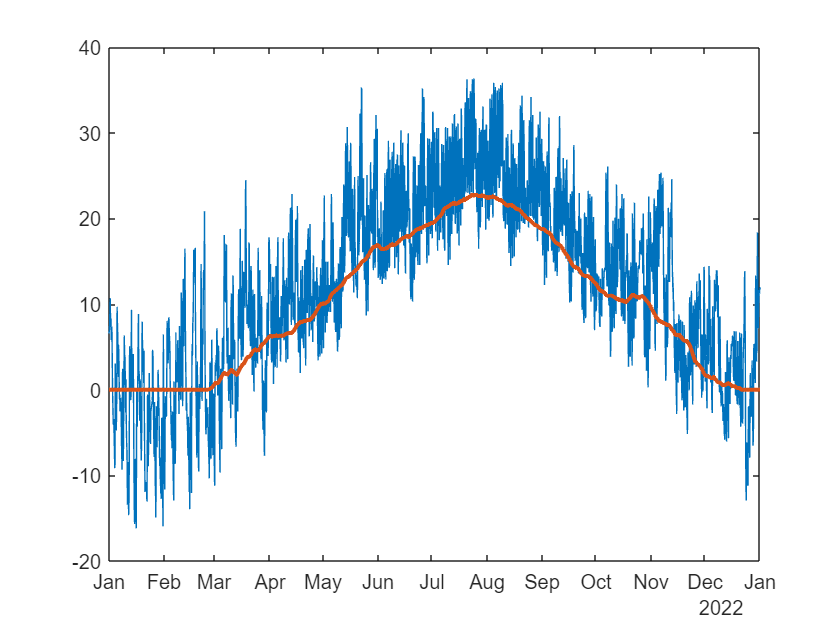

figure
plot(time,temp)
hold on
lakeTemp = smoothdata(temp,"movmean","SmoothingFactor",0.3);
lakeTemp = 0.95*lakeTemp - 2.0;
lakeTemp( lakeTemp < 0.0 ) = 0.0;
plot(time,lakeTemp,LineWidth=2)
hold off

P_0w = 0.61121*exp((18.678-lakeTemp/234.5).*lakeTemp./(257.14+lakeTemp));%PropsSI('P','Q',1,'T',lakeTemp+273.15,'water');
P_0a = 0.61121*exp((18.678-temp/234.5).*temp./(257.14+temp));%PropsSI('P','Q',1,'T',temp+273.15,'water');
e_w  = humidity.*P_0w*10;
e_a  = humidity.*P_0a*10;

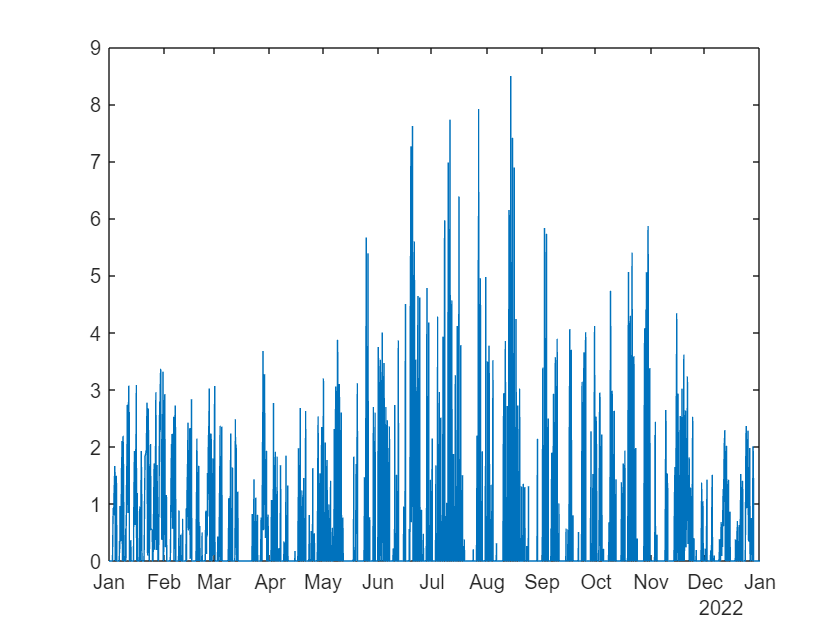

dp = (e_w - e_a)*0.01;
dp( dp < 0) = 0;
figure
plot(time,dp)

## **Visualize Evaporation**

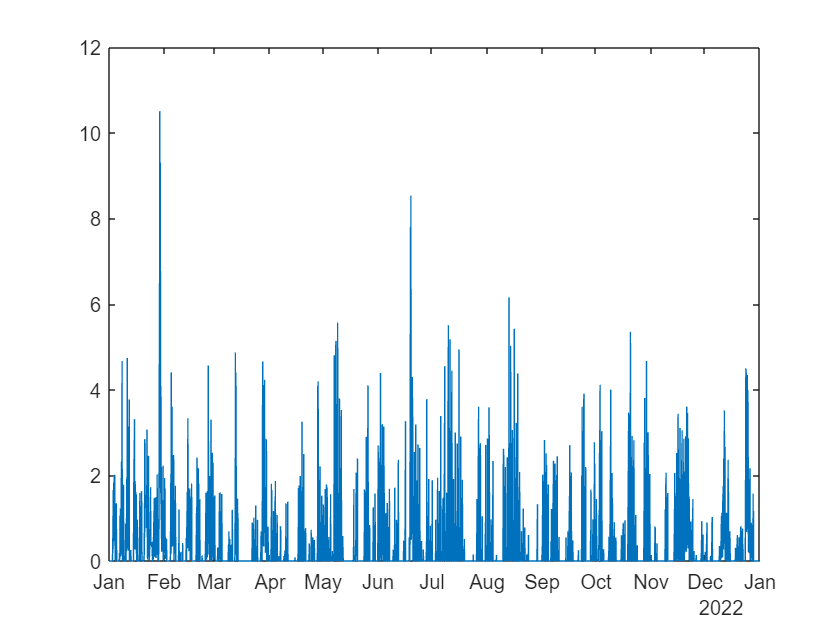

mevap = (0.17+0.30*windSpeed*0.44704).*dp;
figure
plot(time,mevap)

Organize the data

weather = timetable(time,lakeTemp,temp,windSpeed*0.44704,humidity,e_w*0.01,e_a*0.01,data(:,8))

weather = 515451×7 timetable
            time            lakeTemp     temp      Var3      humidity    Var5      Var6     Var7
    ____________________    ________    ______    _______    ________    _____    ______    ____
    01-Jan-2022 00:00:10       0        6.5556          0       91       5.562    8.8428     0  
    01-Jan-2022 00:01:10       0        6.5556          0       91       5.562    8.8428     0  
    01-Jan-2022 00:02:10       0        6.5556          0       91       5.562    8.8428     0  
    01-Jan-2022 00:03:10       0        6.5556          0       91       5.562    8.8428     0  
    01-Jan-2022 00:04:10       0

plot(weather,

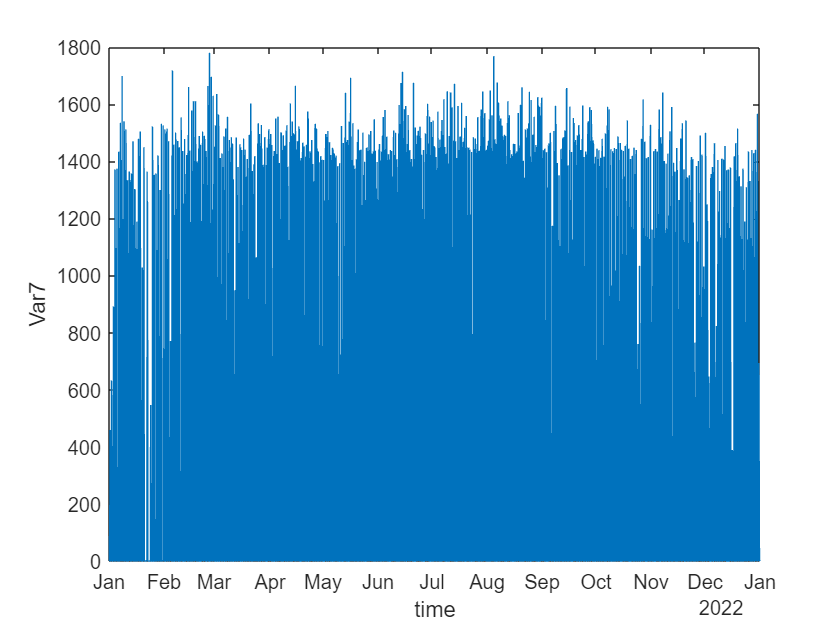

plot(weather,"time","Var7" )

Copyright 2023, The MathWorks, Inc.